%% Build Neural Network

inputSize = 2;      % [t ; F]
outputSize = 1;     % x(t)
numHiddenUnits = 128;

layers = [
    featureInputLayer(inputSize)

    fullyConnectedLayer(numHiddenUnits)
    tanhLayer()

    fullyConnectedLayer(numHiddenUnits)
    tanhLayer()

    fullyConnectedLayer(numHiddenUnits)
    tanhLayer()

    fullyConnectedLayer(numHiddenUnits)
    tanhLayer()

    fullyConnectedLayer(outputSize)
    ];

net = dlnetwork(layers);

deepNetworkDesigner(net)

%% Training Parameters

numIterations = 3000;
learnRate = 0.001;

mp = [];
vp = [];
%% Prepare Data
tSol  = tSol/max(tSol);
F  = F/max(abs(F));
x  = x/max(abs(x));
inputData = [tSol'; F'];

tdata = dlarray(inputData,'CB'); % input of pinn
xdata = dlarray(x','CB'); % output of pinn
col=1000

col = 1000

tcol=linspace(0,10,col)

tcol =          0    0.0100    0.0200    0.0300    0.0400    0.0501    0.0601    0.0701    0.0801    0.0901    0.1001    0.1101    0.1201    0.1301    0.1401    0.1502    0.1602    0.1702    0.1802    0.1902    0.2002    0.2102    0.2202    0.2302    0.2402    0.2503    0.2603    0.2703    0.2803    0.2903    0.3003    0.3103    0.3203    0.3303    0.3403    0.3504    0.3604    0.3704    0.3804    0.3904    0.4004    0.4104    0.4204    0.4304    0.4404    0.4505    0.4605    0.4705    0.4805    0.4905


Fcol=10*sin(2*tcol)

Fcol =          0    0.2002    0.4003    0.6002    0.7999    0.9993    1.1983    1.3968    1.5948    1.7921    1.9887    2.1844    2.3794    2.5733    2.7663    2.9581    3.1487    3.3381    3.5261    3.7127    3.8979    4.0814    4.2634    4.4436    4.6221    4.7986    4.9733    5.1460    5.3166    5.4851    5.6514    5.8154    5.9771    6.1364    6.2932    6.4475    6.5993    6.7483    6.8947    7.0383    7.1791    7.3171    7.4520    7.5840    7.7130    7.8389    7.9616    8.0811    8.1974    8.3104


Col=[tcol;Fcol]

Col =          0    0.0100    0.0200    0.0300    0.0400    0.0501    0.0601    0.0701    0.0801    0.0901    0.1001    0.1101    0.1201    0.1301    0.1401    0.1502    0.1602    0.1702    0.1802    0.1902    0.2002    0.2102    0.2202    0.2302    0.2402    0.2503    0.2603    0.2703    0.2803    0.2903    0.3003    0.3103    0.3203    0.3303    0.3403    0.3504    0.3604    0.3704    0.3804    0.3904    0.4004    0.4104    0.4204    0.4304    0.4404    0.4505    0.4605    0.4705    0.4805    0.4905
         0    0.2002    0.4003    0.6002    0.7999    0.9993    1.1983    1.3968    1.5948    1.7921    1.9887    2.1844    2.3794    2.5733    2.7663    2.9581    3.1487    3.3381    3.5261    3.7127    3.8979    4.0814    4.2634    4.4436    4.6221    4.7986    4.9733    5.1460    5.3166    5.4851    5.6514    5.8154    5.9771    6.1364    6.2932    6.4475    6.5993    6.7483    6.8947    7.0383    7.1791    7.3171    7.4520    7.5840    7.7130    7.8389    7.9616    8.0811    8.1974   

tpinns = dlarray(Col,'CB');

tpinns = dlarray(extractdata(tpinns),'CB');

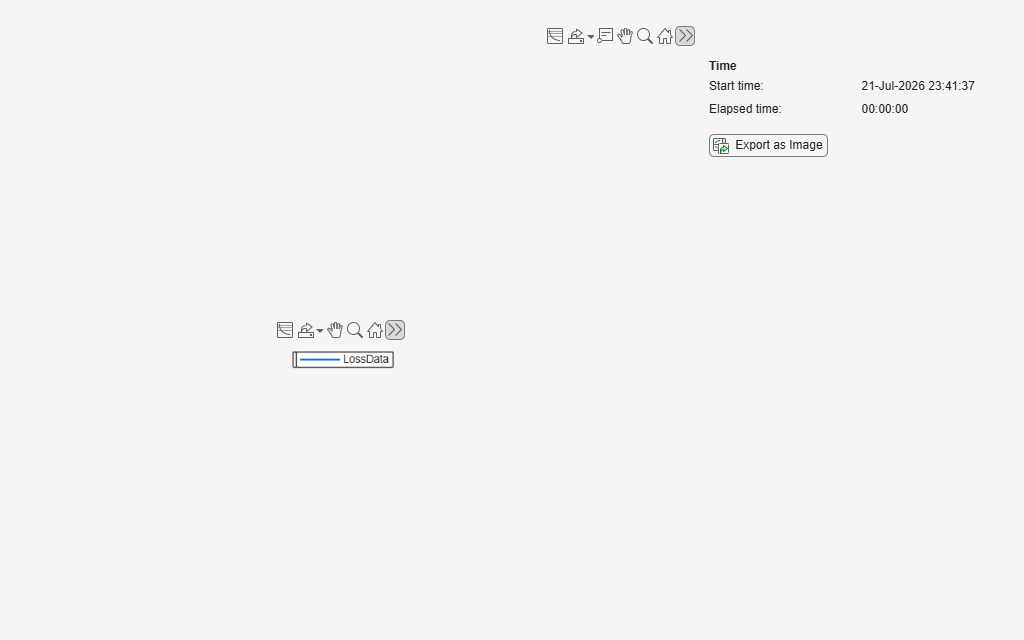

%% Trainable Physical Parameters

mRaw = dlarray(log(6));
cRaw = dlarray(log(2));
kRaw = dlarray(log(10));

mpM = [];
vpM = [];

mpC = [];
vpC = [];

mpK = [];
vpK = [];
%% Training Monitor

monitor = trainingProgressMonitor( ...
    Metrics=["Loss","LossPINN","LossData"]);


accFcn = dlaccelerate(@modelLoss);

%% Loss History

totalLossHistory   = [];
physicsLossHistory = [];
dataLossHistory    = [];

%% Parameter History

mHistory = [];
cHistory = [];
kHistory = [];

Iter = 100


m = 6.0000


c = 2.0000


k = 9.8734



Iter = 200


m = 6.0000


c = 2.0000


k = 9.8754



Iter = 300


m = 6.0000


c = 2.0000


k = 9.8761



Iter = 400


m = 6.0000


c = 2.0000


k = 9.8769



Iter = 500


m = 6.0000


c = 2.0000


k = 9.8779



Iter = 600


m = 6.0000


c = 2.0000


k = 9.8760



Iter = 700


m = 6.0000


c = 2.0000


k = 9.8770



Iter = 800


m = 6.0000


c = 2.0000


k = 9.8721



Iter = 900


m = 6.0000


c = 2.0000


k = 9.8726



Iter = 1000


m = 6.0000


c = 2.0000


k = 9.8737



Iter = 1100


m = 6.0000


c = 2.0000


k = 9.8613



Iter = 1200


m = 6.0000


c = 2.0000


k = 9.8618



Iter = 1300


m = 6.0000


c = 2.0000


k = 9.8628



Iter = 1400


m = 6.0000


c = 2.0000


k = 9.8638



Iter = 1500


m = 6.0000


c = 2.0000


k = 9.8647



Iter = 1600


m = 6.0000


c = 2.0000


k = 9.8460



Iter = 1700


m = 6.0000


c = 2.0000


k = 9.8473



Iter = 1800


m = 6.0000


c = 2.0000


k = 9.8484



Iter = 1900


m = 6.0000


c = 2.0000


k = 9.8493



Iter = 2000


m = 6.0000


c = 2.0000


k = 9.8503



Iter = 2100


m = 6.0000


c = 2.0000


k = 9.8364



Iter = 2200


m = 6.0000


c = 2.0000


k = 9.8321



Iter = 2300


m = 6.0000


c = 2.0000


k = 9.8336



Iter = 2400


m = 6.0000


c = 2.0000


k = 9.8348



Iter = 2500


m = 6.0000


c = 2.0000


k = 9.8355



Iter = 2600


m = 6.0000


c = 2.0000


k = 9.8293



Iter = 2700


m = 6.0000


c = 2.0000


k = 9.8132



Iter = 2800


m = 6.0000


c = 2.0000


k = 9.8151



Iter = 2900


m = 6.0000


c = 2.0000


k = 9.8167



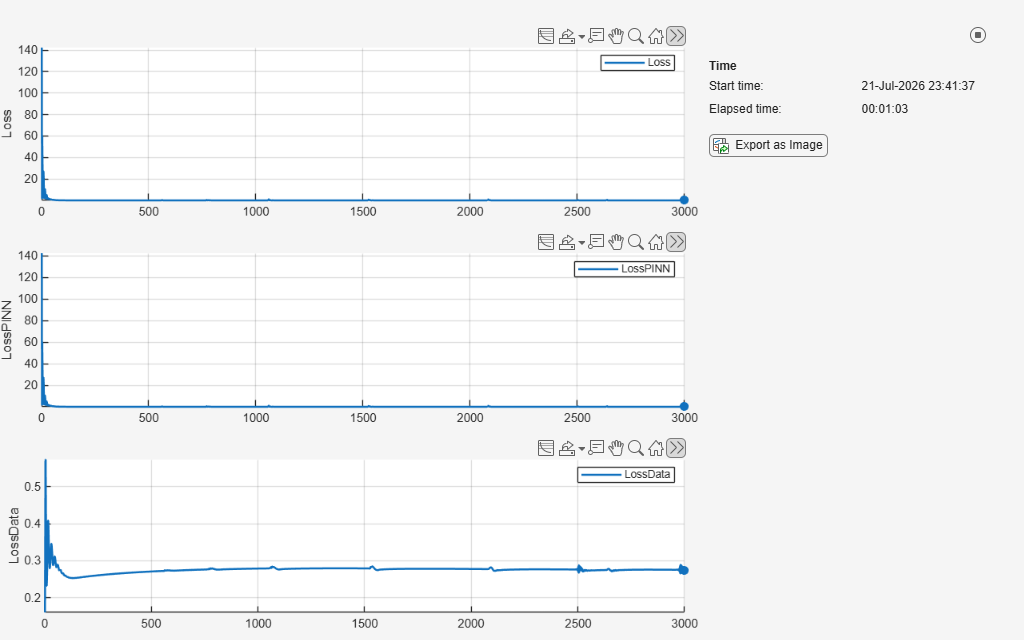

Iter = 3000


m = 6.0000


c = 2.0000


k = 9.8077



%% Training Loop

for iteration = 1:numIterations

    [loss,gradients,gradM,gradC,gradK,...
        lossPinn,lossData] = ...
        dlfeval(accFcn,net,...
        tdata,xdata,tpinns,...
        mRaw,cRaw,kRaw);

    [net,mp,vp] = adamupdate( ...
        net,gradients,mp,vp,...
        iteration,learnRate);

    [mRaw,mpM,vpM] = adamupdate( ...
        mRaw,gradM,mpM,vpM,...
        iteration,learnRate);

    [cRaw,mpC,vpC] = adamupdate( ...
        cRaw,gradC,mpC,vpC,...
        iteration,learnRate);

    [kRaw,mpK,vpK] = adamupdate( ...
        kRaw,gradK,mpK,vpK,...
        iteration,learnRate);

    recordMetrics(monitor,iteration,...
        Loss=loss,...
        LossPINN=lossPinn,...
        LossData=lossData);
    %% Store losses

totalLossHistory(end+1)   = double(extractdata(loss));
physicsLossHistory(end+1) = double(extractdata(lossPinn));
dataLossHistory(end+1)    = double(extractdata(lossData));

%% Store parameters

mHistory(end+1) = double(extractdata(exp(mRaw)));
cHistory(end+1) = double(extractdata(exp(cRaw)));
kHistory(end+1) = double(extractdata(exp(kRaw)));

    if mod(iteration,100)==0

        m = exp(mRaw);
        c = exp(cRaw);
        k = exp(kRaw);

        fprintf('Iter = %d\n',iteration);
        fprintf('m = %.4f\n',extractdata(m));
        fprintf('c = %.4f\n',extractdata(c));
        fprintf('k = %.4f\n\n',extractdata(k));

    end

end

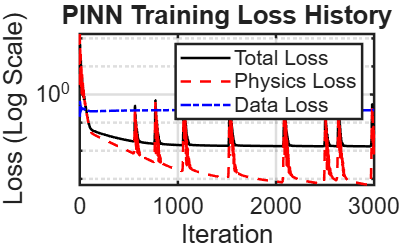

figure;

semilogy(totalLossHistory,'k','LineWidth',1.5);
hold on;
semilogy(physicsLossHistory,'r--','LineWidth',1.5);
semilogy(dataLossHistory,'b-.','LineWidth',1.5);

grid on;
box on;

xlabel('Iteration','FontSize',14);
ylabel('Loss (Log Scale)','FontSize',14);
title('PINN Training Loss History','FontSize',16);

legend('Total Loss','Physics Loss','Data Loss',...
    'Location','northeast');

set(gca,'FontSize',14,'LineWidth',1.5);

exportgraphics(gcf,'Loss_History.png','Resolution',300);

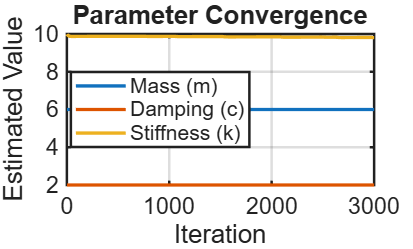

figure;

plot(mHistory,'LineWidth',2);
hold on;

plot(cHistory,'LineWidth',2);

plot(kHistory,'LineWidth',2);

grid on;
box on;

xlabel('Iteration','FontSize',14);
ylabel('Estimated Value','FontSize',14);
title('Parameter Convergence','FontSize',16);

legend('Mass (m)','Damping (c)','Stiffness (k)',...
    'Location','best');

set(gca,'FontSize',14,'LineWidth',1.5);

exportgraphics(gcf,'Parameter_Convergence.png','Resolution',300);

%% Estimated Parameters

m = exp(mRaw);
c = exp(cRaw);
k = exp(kRaw);

fprintf('\nEstimated Parameters\n');


Estimated Parameters



fprintf('m = %.6f\n',extractdata(m));

m = 6.000000


fprintf('c = %.6f\n',extractdata(c));

c = 2.000000


fprintf('k = %.6f\n',extractdata(k));

k = 9.807705


function [loss,gradients,gradM,gradC,gradK,...
    lossPinn,lossData] = ...
    modelLoss(net,tdata,xdata,tpinns,...
    mRaw,cRaw,kRaw)

m = exp(mRaw);
c = exp(cRaw);
k = exp(kRaw);

lossPinn = pinnsLoss(net,tpinns,m,c,k);
lossData = dataLoss(net,tdata,xdata);

loss = 1*lossPinn + 0.05*lossData;

[gradients,gradM,gradC,gradK] = ...
    dlgradient(loss,...
    net.Learnables,...
    mRaw,cRaw,kRaw);

end

function loss = pinnsLoss(net,input,m,c,k)

t = input(1,:);
F = input(2,:);

x = forward(net,input);

xt = dlgradient( ...
    sum(x,'all'), ...
    t, ...
    'EnableHigherDerivatives',true);

xtt = dlgradient( ...
    sum(xt,'all'), ...
    t);

residual = m.*xtt + c.*xt + k.*x - F;

loss = mean(residual.^2,'all');

end

function loss = dataLoss(net,input,xTarget)

xPred = forward(net,input);

loss = mean((xPred - xTarget).^2,'all');

end